# MAIN_EXP_3D_SAMPLING_ADJUST: Sampling adjustment experiments

This script performs the sampling adjustment on real data

The results are stored in folder "./results" as follows:

-  adjustFunc: Variable for the frequency adjustment obtained.

 Requirements: MATLAB R2020b

 Copyright (c) 2021-2022, Ruiki KOBAYASHI and Shogo MURAMATSU

 All rights reserved.

 Contact address: Shogo MURAMATSU,

    Faculty of Engineering, Niigata University,

    8050 2-no-cho Ikarashi, Nishi-ku,

    Niigata, 950-2181, JAPAN

    http://msiplab.eng.niigata-u.ac.jp/

## Initial setting

S = load('./materials/tape.mat','ObsData');
ObsData = S.ObsData;
[obsx,obsy,obsz] = size(ObsData);
obsz

obsz = 5000

## Bias removal

nLen = 21;
lpf = ones(nLen,1)/nLen;
lpf = permute(lpf,[2 3 1]);
ObsData = ObsData - imfilter(ObsData,lpf,'symmetric');

## Peak search

len = 100;
div = 100;
stsize = div-round(len/obsz*div)+1;
win = hamming(len,'periodic');
freq = zeros(stsize,1);
mval = zeros(stsize,1);
for i = 1:obsx
    for j = 1:obsy
        s = abs(stft(squeeze(ObsData(i,j,:)),'Window',win,'OverlapLength',len-obsz/div,'FFTLength',2048)); 
        [val,index] = max(s(end/2+1:end,:));
        freq = freq+index(:); % Corresponds to mean of max freq at each depth
        mval = mval+val(:);
    end
end

## Generate resampling function

idcs = find(mval>0.5*max(mval,[],'all'));
%plot(idcs,mval(idcs),'o')
%plot(idcs,freq(idcs),'o')
p = polyfit(idcs,freq(idcs),1);
imin = min(idcs);
imax = max(idcs);
dc = polyval(p,imin:imin+div-1);
%de = 1e-5;
depthEst = dc(end)/dc(1);
disp("depthEst = " + depthEst)

depthEst = 1.4557


funcEst = linspace(depthEst,1,obsz); % depthEst:-(depthEst-1)/obsz:1+de;
for i = 2:obsz
    funcEst(i) = funcEst(i-1) + 1/funcEst(i);
end
disp(depthEst)

    1.4557



## Store results

dt = char(datetime('now','TimeZone','local','Format','yyyy-MM-dd-HH-mm'));
targetdir = "./results/exp_smpadj_" + dt;
if exist(targetdir,'dir') ~= 7
    mkdir(targetdir)
end
save(targetdir + "/adjustFunc",'funcEst','depthEst');

## Sampling adjustment

tEst = support.fcn_resampling(ObsData,funcEst,0);

## Display results and generate figures

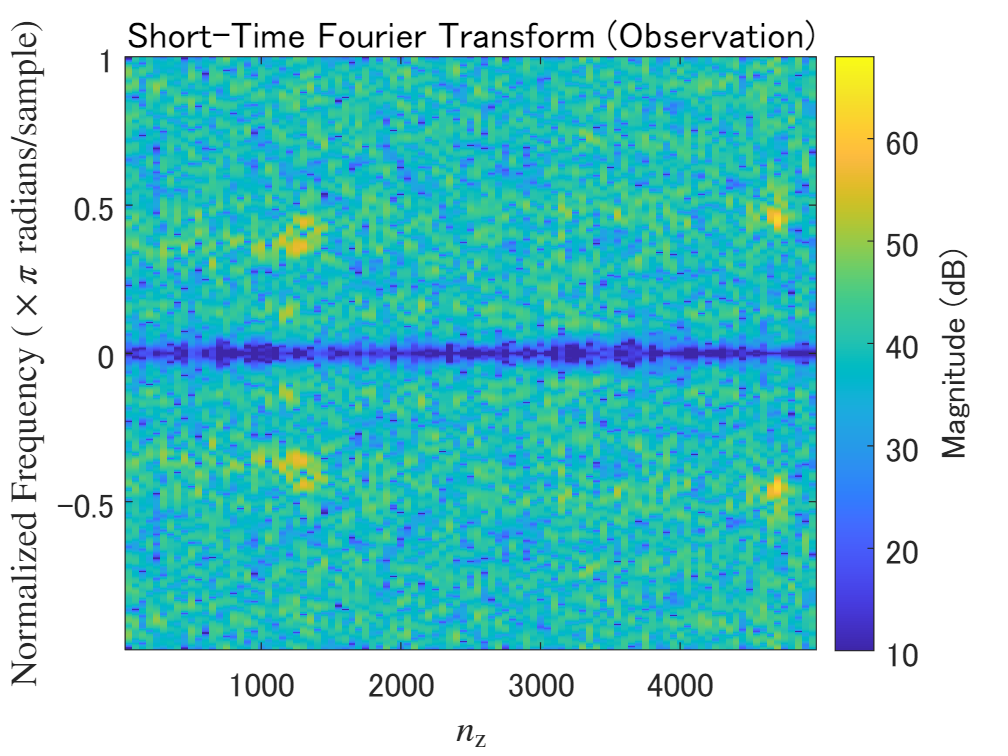

tfigname = @(x) "./results/fig12"+string(char(96+x))+"rev.png";
config_.win = win;
config_.len = len;
config_.obsz = obsz;
config_.div = div;
isubfig = 1;

% Observation
hfig = figure;
fcn_stftview_(hfig,ObsData,"Observation",config_)
drawnow
exportgraphics(hfig,tfigname(isubfig),"Resolution",300);

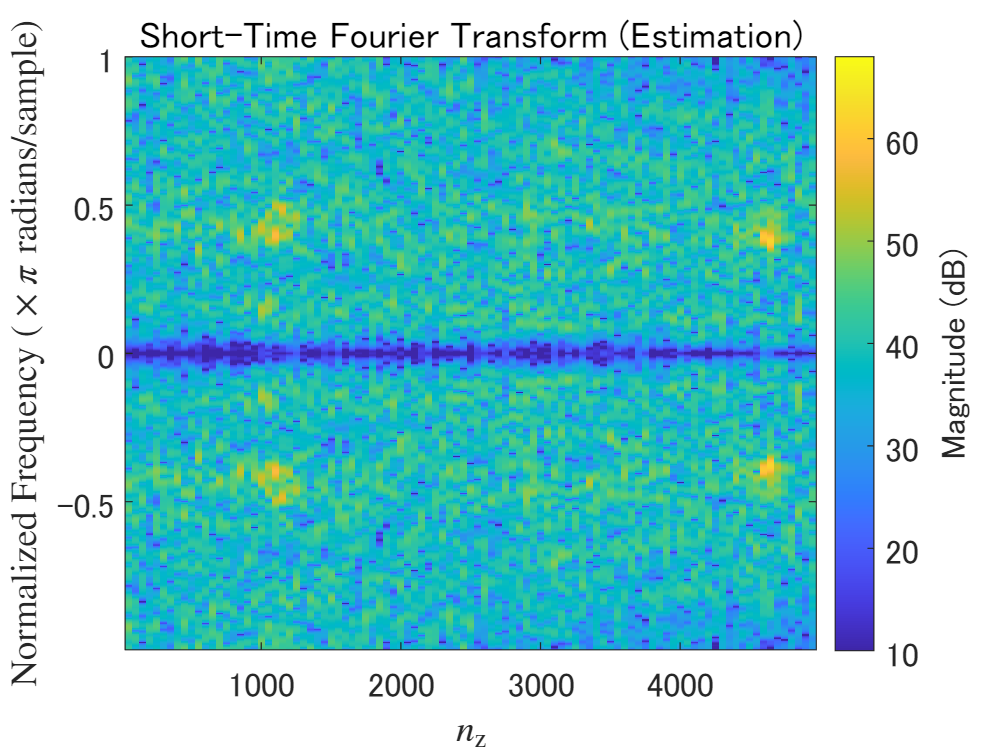

isubfig =isubfig+1;
%close(hfig)

% Estimation
hfig = figure;
fcn_stftview_(hfig,tEst,"Estimation",config_)
drawnow
exportgraphics(hfig,tfigname(isubfig),"Resolution",300);

%close(hfig)


## Functions for visualization

function fcn_stftview_(hfig,array3d,signalname,config)
win = config.win;
len = config.len;
obsz = config.obsz;
div = config.div;
figure(hfig)
stft(squeeze(array3d(1,1,:)),'Window',win,'OverlapLength',len-obsz/div,'FFTLength',2048);
ylabel("Normalized Frequency ($\times\pi$ radians/sample)","Interpreter","latex")
xlabel("$n_\mathrm{z}$", "Interpreter","latex")
title("Short-Time Fourier Transform ("+signalname+")")
caxis([10 68])
yticks(-1:0.5:1)
%
hcb = hfig.Children(1);
hcb.Label.String = 'Magnitude (dB)';
hcb.FontSize = 14;
hax = hfig.Children(2);
hax.FontSize = 14;
end